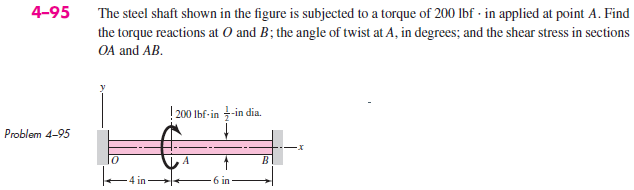

# given

u = symunit;
D = 0.5*u.in;
T_A = 200*u.lbf*u.in;

# section properties

E = 30e6*u.psi;
nu = 0.291;
G = E/(2*(1+nu));
J = sympi*(D/2)^4/2;

# continuity condition

eqn = sym.zeros(5,1);
T_OA = sym('T_OA');
T_AB = sym('T_AB');
L_OA = 4*u.in;
L_AB = 6*u.in;
eqn(1) = T_OA*L_OA/(G*J) == T_AB*L_AB/(G*J);

# angle of twist

phi_A = sym('phi_A');
eqn(2) = phi_A == T_OA*L_OA/(G*J);

# shear stresses

C = D/2;
tau_OA = sym('tau_OA');
tau_AB = sym('tau_AB');
eqn(3) = tau_OA == T_OA*C/J;
eqn(4) = tau_AB == T_AB*C/J;

# statics

eqn(5) = T_OA+T_AB+T_A == 0;

# solutions

[T_OA T_AB phi_A tau_OA tau_AB] = solve(eqn, T_OA, T_AB, phi_A, tau_OA, tau_AB); %#ok
T_OA

$$T\_OA = -120\,\mathrm{in}\,\mathrm{lbf}$$

T_AB

$$T\_AB = -80\,\mathrm{in}\,\mathrm{lbf}$$

phi_A = rewrite(simplify(phi_A)*u.rad, u.deg);
phi_A_vpa = vpa(phi_A, 3) %#ok

$$phi\_A\_vpa = -0.386\,\deg$$

tau_OA = rewrite(tau_OA, u.ksi);
tau_OA_vpa = vpa(tau_OA, 3) %#ok

$$tau\_OA\_vpa = -4.89\,\mathrm{ksi}$$

tau_AB = rewrite(tau_AB, u.ksi);
tau_AB_vpa = vpa(tau_AB, 3) %#ok

$$tau\_AB\_vpa = -3.26\,\mathrm{ksi}$$

clear phi_A_vpa tau_OA_vpa tau_AB_vpa;